clear;

## Question 1

**Solution**

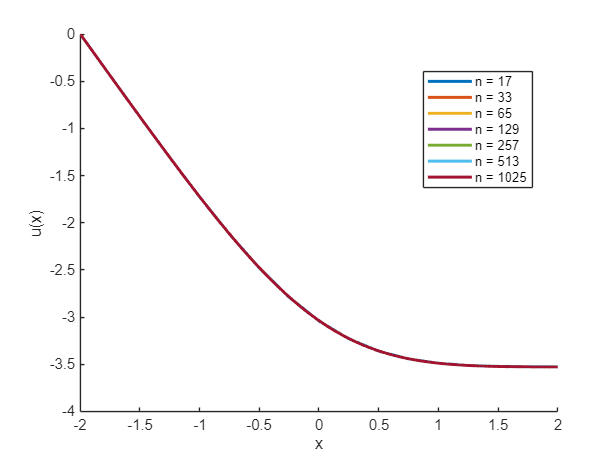

% BVP: u''(x) = exp(-x^2), u(-2) = 0, u'(2) = 0

% globals
n = 2.^(4:10); n=n+1;
f = @(x) exp(-x.^2);
H = cell(1,3);
Y = cell(1,3);

% setting up plot
f1q1 = figure();
xlabel('x'); ylabel('u(x)');
legend('location', 'best');
formatSpec = 'n = %d';

for i = 1:length(n)
    % solve
    [x,y,h,~] = poisson1D([-2 2], n(i), f, [0 0]);
    % for comparison
    H{i} = h;
    Y{i} = y(1 : 2^(i-1) : end);
    % plot
    str = sprintf(formatSpec, n(i));
    hold on;
    plot(x, y, 'LineStyle', '-', 'LineWidth', 2, ...
        'DisplayName', str);
end
exportgraphics(f1q1, [pwd '/Figures/HW3_q1_solution.png']);

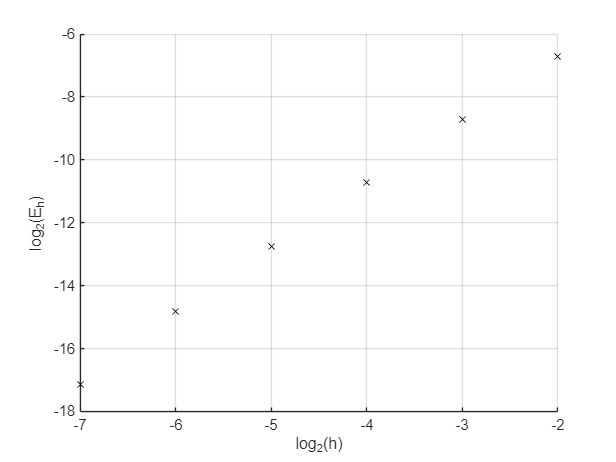

f2q1 = figure();
xlabel('log_2(h)'); ylabel('log_2(E_h)');
grid on;
% xscale('log'); yscale('log');


for i = 1 : length(n)-1
    E = norm(Y{end}-Y{i});

    hold on;
    plot(log2(H{i}), log2(E), 'kx');
end
exportgraphics(f2q1, [pwd '/Figures/HW3_q1_error.png']);

**Experimenting**

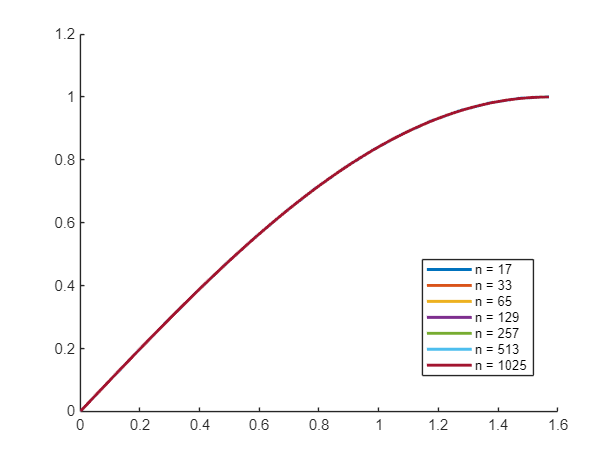

figure();
legend('location', 'best');
formatSpec = 'n = %d';
g = @(x) -sin(x);
gTrue = @(x) sin(x);

for i = 1:length(n)
    [x,y,~] = poisson1D([0 pi/2], n(i), g, [0 0]);
    
    str = sprintf(formatSpec, n(i));
    hold on;
    plot(x,y, 'LineStyle', '-', 'LineWidth', 2, ...
        'DisplayName', str);
end

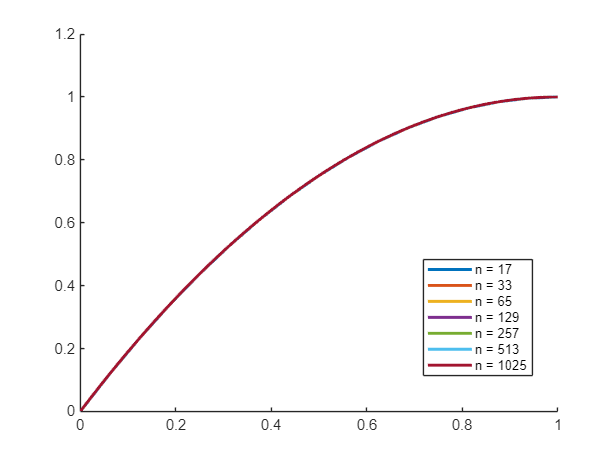

figure();
legend('location', 'best');
formatSpec = 'n = %d';

k = @(x) 0*x - 2;
kTrue = @(x) 2*x - x.^2;

for i = 1:length(n)
    [x,y,~] = poisson1D([0 1], n(i), k, [0 0]);
    
    str = sprintf(formatSpec, n(i));
    hold on;
    plot(x,y, 'LineStyle', '-', 'LineWidth', 2, ...
        'DisplayName', str);
end